# Assignment 3

Collaborated with: Aditya Rathi

Ruchita Sinha

## Q1. (a)

Initialize transfer function

warning('off','all')
s = tf('s');
G = exp(-0.005*s)*(-s+3)/((s+2)*(s+1000));

Set random intial values for wc, Gm, and Pm. Set 'a' and 'b' a bit wide apart from the wc

wc = 10; 
a = 0.0003; 
b = 3000;
Gm = 1;
Pm = 20;

Create a loop to update the value of wc so that we get the maximum value of wc where the required system parameters are satisfied. The value of K has been calculated by hand to eliminate the time delay error in MATLAB.

Gm = 2.1877

Pm = 41.1215

Wcg = 2.9535

Wcp = 1.3500

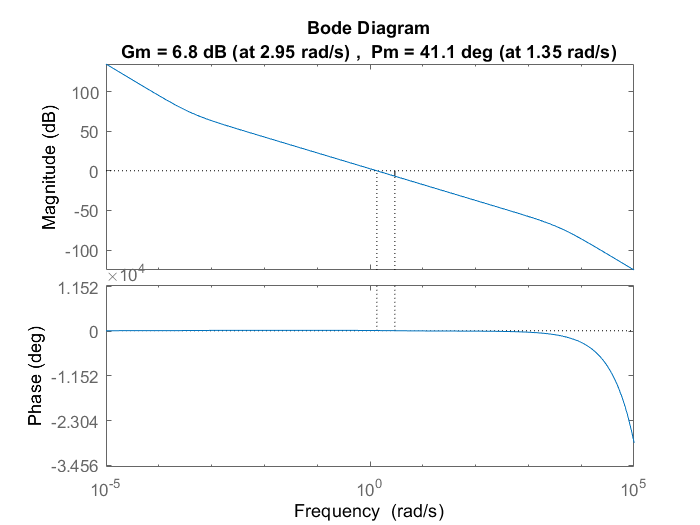

wc = 1.3500

while(Pm<40 || Gm < 10^(6/20))
    L = ((-s+3)/(s+3))*exp(-0.005*s)*(s+a*wc)/((s^2)*(s+b*wc));
    K = (s+a*wc)*(s+2)*(s+1000)/((s+b*wc)*(s+3)*s^2);
    [mag2,phase] = bode(G*K,wc);
    K = K/mag2;
    [Gm,Pm,Wcg,Wcp] = margin(G*K);
    if (Pm > 40 && Gm > 10^(6/20))
        [Gm,Pm,Wcg,Wcp] = margin(G*K)
        margin(G*K)
        wc
        break
    end
    wc = wc - 0.05;
end

magnitude bode plot of the sensitivity function.

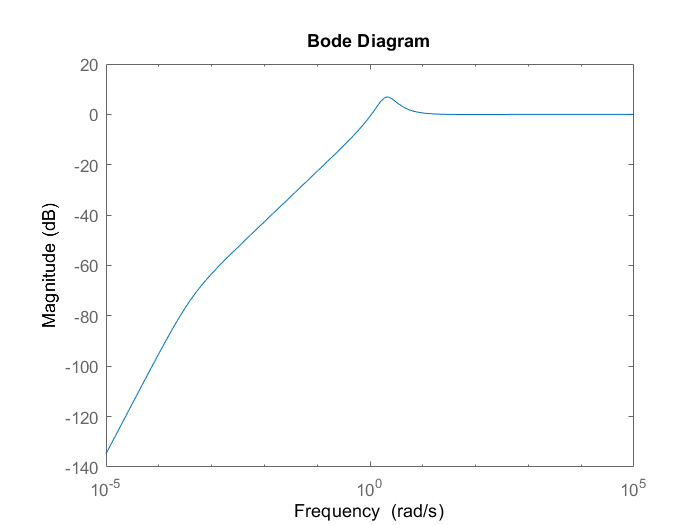

bodemag(1/(1+G*K))